## ECEN 142L Communications and Networking Lab

## Lab 5: Multiple Access Protocols

Dylan Thornburg & Evelyn Arellano Quintero

Imagine this: you are sitting with your friends, and you want to say something to everyone. Now imagine everyone else is trying to do the same thing. The result is that everyone is shouting, and nobody can hear anybody else! We have the same problem in communications - how can we have multiple people share a channel and still make sure everyone gets served? The answer is multiple access protocols.

Today’s Objective: Learn about multiple access fundamentals by implementing our own version of FDMA and TDMA.

We will be using some of the terminology from 142 Lecture, so if anything seems unfamiliar, be sure to review any lecture materials you have been given so far.

## Part 1: Data Generation

To keep things relatively simple, we are going to make our program simulate only 2 users. That is, we have 2 people who want to transmit data simultaneously.

**Step 1:**

Before we make our signals, we will need a time vector. Create a vector tthat goes from -1 to 14.99, with a sampling rate of 100 Hz. (remember that sampling period T is 1/Fs)

Now, create two signals of all zeros called user1 and user2. They should be the same length as t- these will hold the data each user wants to transmit.

Paste the following lines into your program:

        rand1 = 2*round(rand(1,128))-1;

        rand2 = 2*round(rand(1,128))-1;

We will use rand1 and rand2 to help us generate unique signals for each user.

clear;
clc;
close all;

Fs = 100;
T = 1/Fs;
t = -1:T:14.99;
user1 = zeros(1,length(t));
user2 = zeros(1,length(t));

rand1 = 2*round(rand(1,128))-1;
rand2 = 2*round(rand(1,128))-1;

Look up the rand() function - what transformation did we apply, and what is the result?

**rand() will generate random decimals between 0 and 1. We make a 1x128 vector with (1,128) so we have 128 random vals. We then round making every random val either 0 or 1 exactly, then multiply by 2 getting 0 or 2 exactly. Lastly we subtract by 1, leaving us with a random collection of -1s and 1s.**

**Step 2:**

The signal we will be using as user transmitted information is the sinc function:

        sinc((t-(i-1)*0.1)/0.1);

Where i is an integer. Write a for loop that starts at one and iterates through 128 values of i. At each step, add a new sinc to both user1 and user2, making sure to use the rand values to make each user’s signal distinct. Plot both signals in one plot. **Show your results from Part 1 to the TA.**

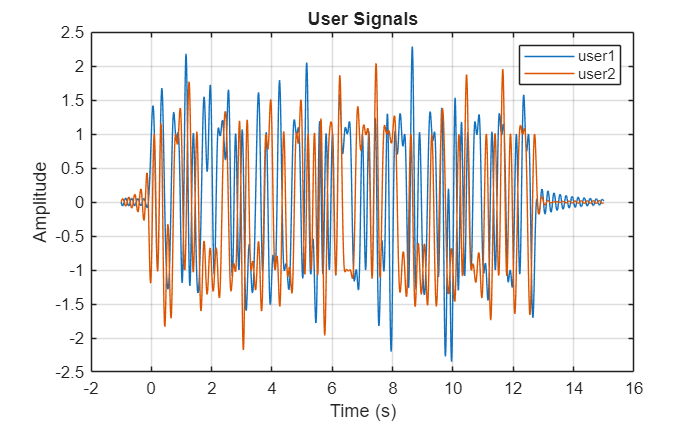

for i = 1:128
    user1 = user1 + rand1(i) * sinc((t-(i-1)*0.1)/0.1);
    user2 = user2 + rand2(i) * sinc((t-(i-1)*0.1)/0.1);
end

figure;
plot(t, user1);
hold on;
plot(t, user2);
hold off;
legend('user1','user2');
xlabel('Time (s)');
ylabel('Amplitude');
title('User Signals');
grid on;

Are the signals visibly different?

**Yes they are. This makes sense too because the numbers are random.**

## Part 2: TDMA

Time Division Multiple Access (TDMA) is a channel access method that works by dividing up the channel into chunks in time.

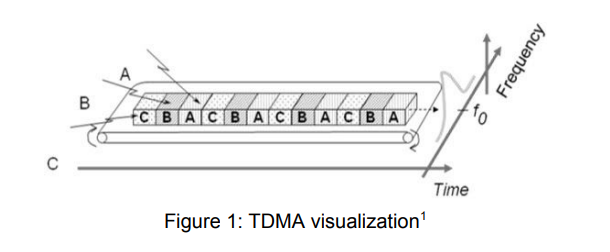

Lets see if we can make our own version using the signals we defined above.

**Step 1:**

The first thing we need for our TDMA implementation is a time division - this is the ‘slot’, or the channel division interval. Copy this code into your program:

        time_div = 0.0100; % seconds

When writing our TDMA code, it will be easier to think of our slots in terms of samples rather than in seconds. Create a new variable sample_div, and assign it 1/time_div.

With those defined, we can do the TDMA. Let’s think about how to do it. What we want to do is interleave (or multiplex) the two signals into one. If our sample_div was just one sample, we would want our output signal to be something like this:

        xTDMA = [user1(1), user2(1), user1(2), user2(2), … user1(N), user2(N)];

And if sample_div was 2 samples, it would look like this:

        xTDMA = [user1(1), user1(2), user2(1), user2(2), …];

Looking at those examples, we can get some intuition about the tradeoffs we make with TDMA. We can see that we are dividing the total amount of time sending a signal by 2 users, so the effective data rate is now ½ of what it would be by just sending one signal. If we wanted to keep the effective data rate the same, we would need to double the bandwidth.

Remembering the concatenation methods we learned in lab 1, write code to interleave the two signals according to sample_div. There are a number of equally good ways to do this, so choose whatever you are most comfortable with. When you are sure your result is correct, plot it.

(Hint: check how long your input signals are, and ask yourself how long the output TDMA signal should be)

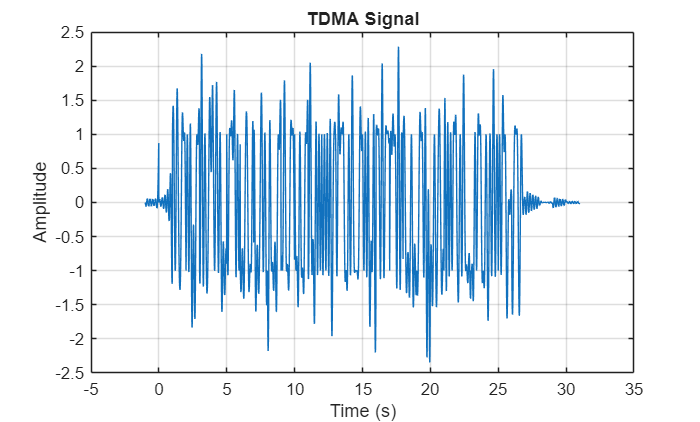

time_div = 0.0100; % seconds

sample_div = 1/time_div;

xTDMA = [];

for i = 1:sample_div:length(t)
    xTDMA = [xTDMA, user1(i:i+sample_div-1), user2(i:i+sample_div-1)];
end

t_TDMA = t(1):time_div:(t(1) + (length(xTDMA)-1)*time_div);

figure;
plot(t_TDMA, xTDMA);
xlabel('Time (s)');
ylabel('Amplitude');
title('TDMA Signal');
grid on;

**Step 2:**

Let’s revisit the FFT recipe we defined in lab 1. Copy the code below into your program.

X_user1 = fft(user1);

shift_user1 = fftshift(X_user1);

freqaxis_user = Fs*(linspace(-0.5,0.5,length(t)));

plot(freqaxis_user, abs(shift_user1));

This shows the frequency spectrum of your user1 signal. Using that as a reference, plot the frequency spectrum of user1, user2, and your TDMA signal on one plot (you will need to create a different freqaxis for the TDMA signal).

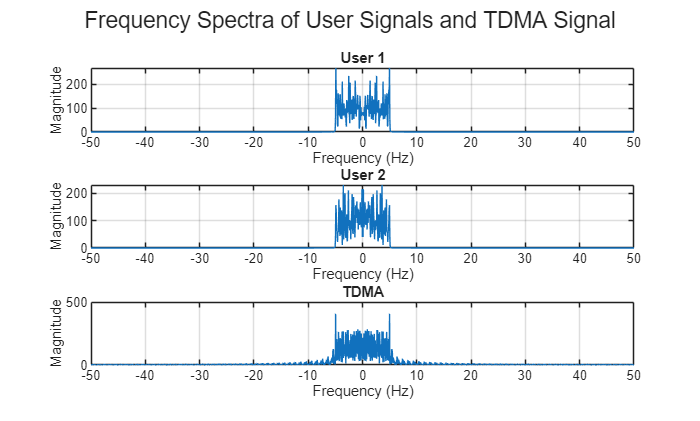

X_user1 = fft(user1);
shift_user1 = fftshift(X_user1);
freqaxis_user = Fs*(linspace(-0.5,0.5,length(t)));

X_user2 = fft(user2);
shift_user2 = fftshift(X_user2);

X_TDMA = fft(xTDMA);
shift_TDMA = fftshift(X_TDMA);
freqaxis_TDMA = Fs*(linspace(-0.5,0.5,length(xTDMA)));


figure;

subplot(3,1,1);
plot(freqaxis_user, abs(shift_user1));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('User 1');
grid on;

subplot(3,1,2);
plot(freqaxis_user, abs(shift_user2));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('User 2');
grid on;

subplot(3,1,3);
plot(freqaxis_TDMA, abs(shift_TDMA));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('TDMA');
grid on;

% Optional overall title
sgtitle('Frequency Spectra of User Signals and TDMA Signal');

What conclusions can you draw from these plots?

**User1 and User2 look the same but not identical (as expected) while the TDMA signal (due to different spectrum) has altered bandwidth and magnitude.**

**Step 3:**

Now lets see if we can recover the original signals from the TDMA signal. Copy the code below:

        rx_TDMA = xTDMA +.1*randn(size(xTDMA));

        rx_user1 = zeros(1, length(t));

        rx_user2 = zeros(1, length(t));

In communications, rx is a shorthand for a received signal. Notice also how we added some white noise to the received TDMA signal - a received signal will never be free from environmental noise.

Next, write some code to do the TDMA demodulation. This will be the inverse function from the code you wrote in step 1. Make 2 plots, each one comparing a user signal to its recieved version.

Demo your working code for this section to the TA.

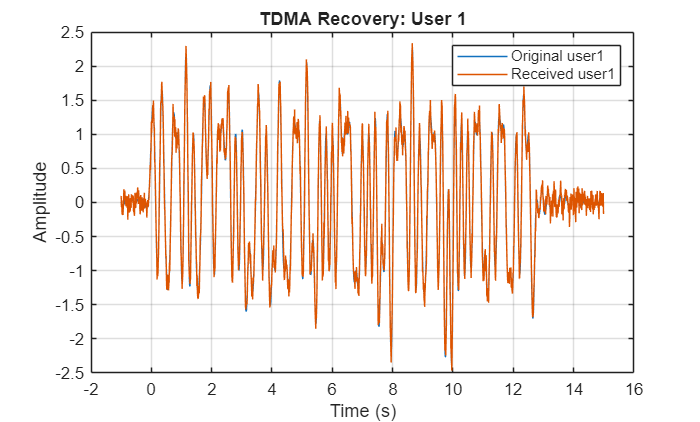

rx_TDMA = xTDMA + .1*randn(size(xTDMA));
rx_user1 = zeros(1, length(t));
rx_user2 = zeros(1, length(t));
rx_index = 1;

for i = 1:sample_div:length(t)
    idx_end = min(i + sample_div - 1, length(t));
    block_len = idx_end - i + 1;

    rx_user1(i:idx_end) = rx_TDMA(rx_index:rx_index + block_len - 1);
    rx_index = rx_index + block_len;

    rx_user2(i:idx_end) = rx_TDMA(rx_index:rx_index + block_len - 1);
    rx_index = rx_index + block_len;
end

figure;
plot(t, user1);
hold on;
plot(t, rx_user1);
hold off;
legend('Original user1','Received user1');
xlabel('Time (s)');
ylabel('Amplitude');
title('TDMA Recovery: User 1');
grid on;

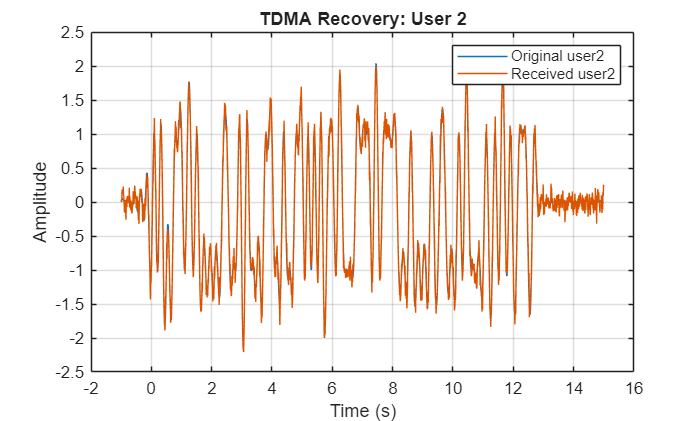

figure;
plot(t, user2);
hold on;
plot(t, rx_user2);
hold off;
legend('Original user2','Received user2');
xlabel('Time (s)');
ylabel('Amplitude');
title('TDMA Recovery: User 2');
grid on;

Can you tell that the received signal is the same?

**Yes, even if the noise obscures it slightly.**

## Part 3: FDMA

Frequency Division Multiple Access, or FDMA for short, is a technique for splitting up signals by carrier frequency. Each signal is carried by a different frequency, so we can split the signals apart at the receiver with some simple filters.

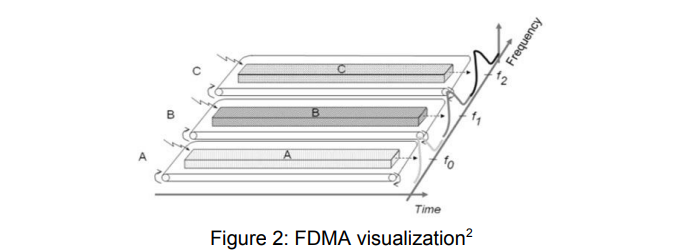

Lets see if we can implement our own FDMA using the principles of modulation we learned in lecture.

**Step 1:**

To begin our implementation, we should figure out how far apart in frequency to space our signals. Go back to FFT plots you made in part 2 and verify that the signals have a bandwidth of about 10 Hz.

To be safe, we will space our signals by 2x the user bandwidth, so about 20 Hz. Create a variable called freq_spacing to store that number. Recognize that there is a tradeoff here - the larger our spacing, the easier it is to tell the individual signals apart, but the less information we can send over this channel.

Next, we will create our modulator. Create a variable modulator that is a cosine with a fundamental frequency of freq_spacing.

Our modulator is all we need to do FDMA - we can apply it with the following line:

        xFDMA = user1 + sqrt(2)*user2.*modulator;

Plot the signal and describe how it looks.

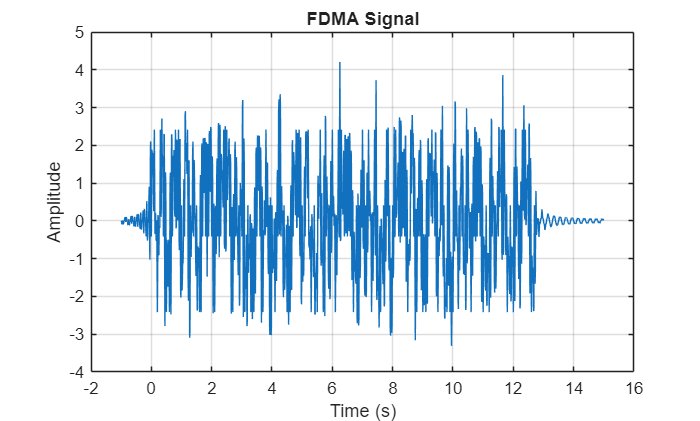

freq_spacing = 20;

modulator = cos(2*pi*freq_spacing*t);

xFDMA = user1 + sqrt(2)*user2.*modulator;

figure;
plot(t, xFDMA);
xlabel('Time (s)');
ylabel('Amplitude');
title('FDMA Signal');
grid on;

**It looks like the original signal but oscillating a bit faster. This is because of the multiplied cosine component on user2. **

**Step 2:**

To get a better understanding of what’s going on, let’s take a look at our signals in the frequency domain. Remembering the FFT recipe from the last section, plot the FFT’s of both input signals and the FDMA signal on the same plot. Describe how it looks - is it what you expected?

In another figure, plot the FDMA signal again, but this time in dB. Simply change the plot command to:

        plot(freqaxis, 10*log10(abs(shift_FDMA)));

How did that change the plot?

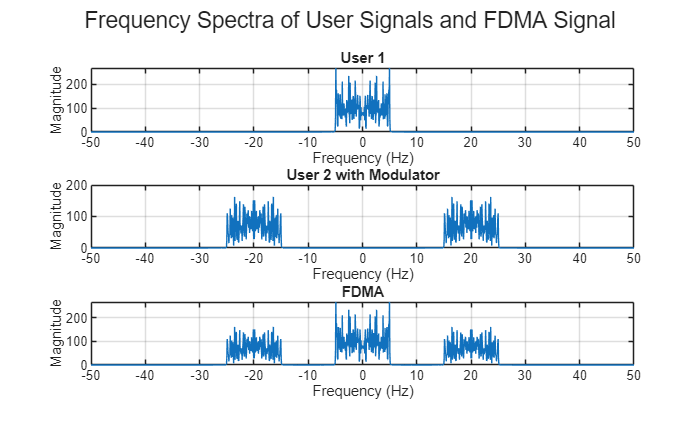

X_user1 = fft(user1);
shift_user1 = fftshift(X_user1);

X_user2 = fft(sqrt(2)*user2.*modulator);
shift_user2 = fftshift(X_user2);

X_FDMA = fft(xFDMA);
shift_FDMA = fftshift(X_FDMA);

freqaxis = Fs*(linspace(-0.5,0.5,length(t)));

figure;

subplot(3,1,1);
plot(freqaxis, abs(shift_user1));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('User 1');
grid on;

subplot(3,1,2);
plot(freqaxis, abs(shift_user2));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('User 2 with Modulator');
grid on;

subplot(3,1,3);
plot(freqaxis, abs(shift_FDMA));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('FDMA');
grid on;

sgtitle('Frequency Spectra of User Signals and FDMA Signal');

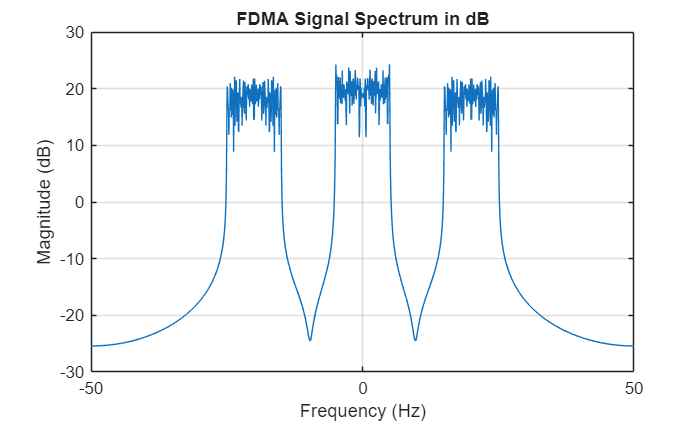

figure;
plot(freqaxis,10*log10(abs(shift_FDMA)));
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('FDMA Signal Spectrum in dB');
grid on;

**We now see that user2 is centered around 20 (and -20) Hz.**

How did "plot(freqaxis,10*log10(abs(shift_FDMA)));" change the plot?

**Plotting in the decibal scale compresses the vertical magnitude, making the peaks visually look a lot closer in value.**

**Step 3:**

We said above that we would need a filter to demodulate the FDMA signals, so lets get to work building one.

Matlab makes designing these filters easy with the filterDesigner. Read the page on how it works at

https://www.mathworks.com/help/signal/examples/introduction-to-filter-designer.html

Open up filterDesigner, and design a filter to extract the signal for user1. You can decide how to build your filter as long as it works! If you have any questions, consult with the TA.

Once you are finished, save your filter to the matlab workspace and name it fdma_lowpass. We may want to save this and use it later, so run the following command:

        save('fdma_lowpass.mat','fdma_lowpass');

This will allow us to use this filter in the future without having to re-design it every time. To load the filter another time, use:

        load('fdma_lowpass.mat');

save('fdma_lowpass.mat','fdma_lowpass');
load('fdma_lowpass.mat');

**Step 4:**

With our filter in place, we can go about demodulating the FDMA signal. First, add some white noise like we did with TDMA.

        received = xFDMA +.1*randn(size(xFDMA));

Let's extract the first signal by using our lowpass filter. Paste and run the code below:

        lowpassed = filter(fdma_lowpass, 1, recieved);

Plot this new signal in frequency. Does it look like you wanted your low pass filtered signal to look? If it doesn't, go back and repeat step 3. If it does, continue by plotting the low pass filtered signal in time on the same plot as user1. 

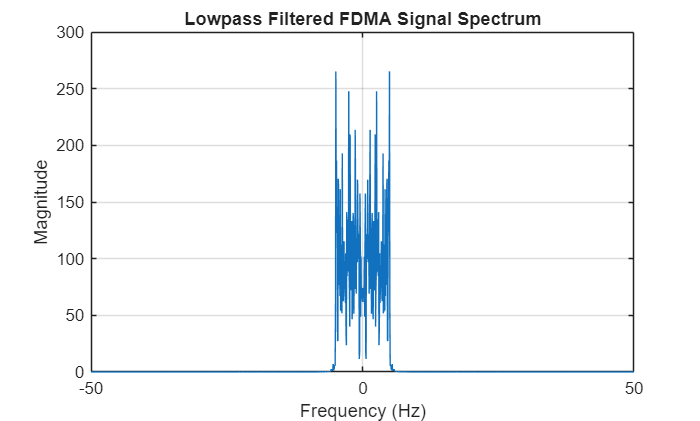

received = xFDMA + .1*randn(size(xFDMA));
lowpassed = filter(fdma_lowpass, 1, received);
X_lowpassed = fft(lowpassed);
shift_lowpassed = fftshift(X_lowpassed);

figure;
plot(freqaxis,abs(shift_lowpassed));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Lowpass Filtered FDMA Signal Spectrum');
grid on;

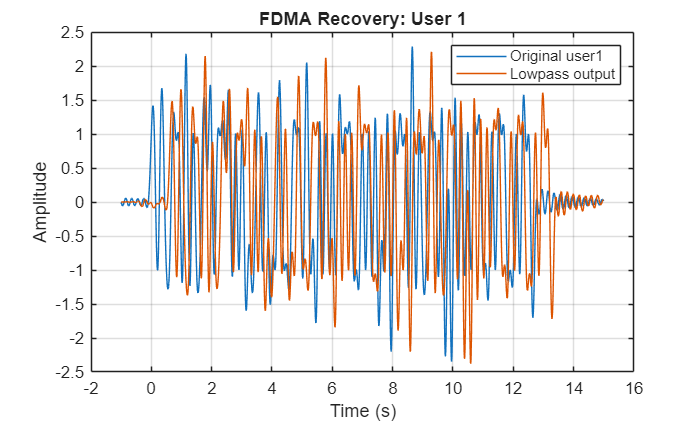


figure;
plot(t, user1);
hold on;
plot(t, lowpassed);
hold off;
legend('Original user1','Lowpass output');
xlabel('Time (s)');
ylabel('Amplitude');
title('FDMA Recovery: User 1');
grid on;

How similar are the two signals? (there will be what looks like a shift due to the filter, we can ignore that)

**The signals are the exact same (ignoring the shift) which is what we want.**

**Step 5:**

Let’s now focus on the frequency shifted signal. Remembering the demodulator will be the same frequency cosine as the modulator, demodulate the signal and apply the same low pass filter. Repeat the plots for step 4. Demo your solutions to the TA.

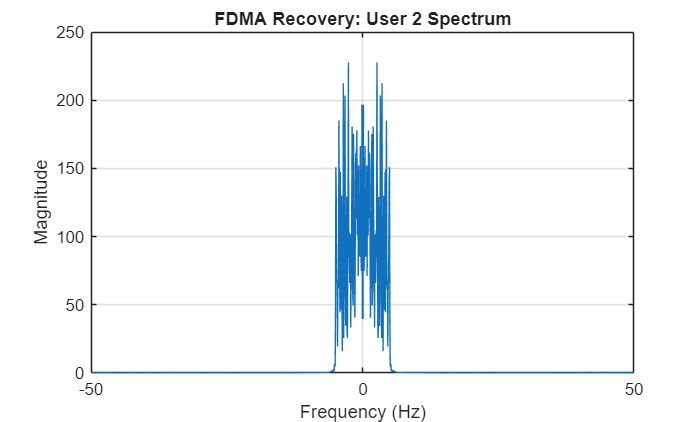

demodulated = sqrt(2)*received.*modulator;
rx_user2_FDMA = filter(fdma_lowpass,1,demodulated);
X_user2_FDMA = fft(rx_user2_FDMA);
shift_user2_FDMA = fftshift(X_user2_FDMA);

figure;
plot(freqaxis,abs(shift_user2_FDMA));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('FDMA Recovery: User 2 Spectrum');
grid on;

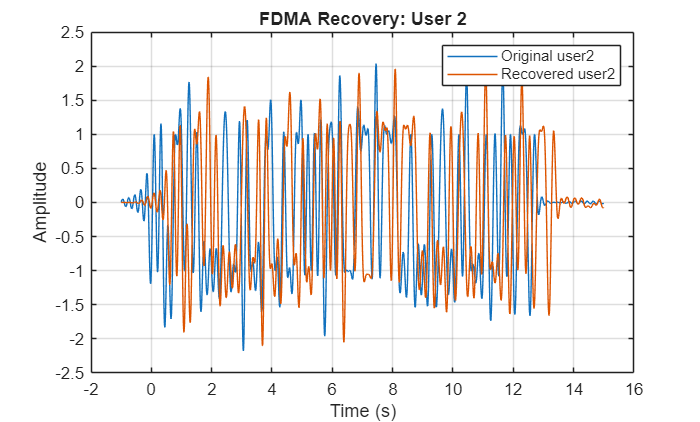


figure;
plot(t, user2);
hold on;
plot(t, rx_user2_FDMA);
hold off;
legend('Original user2','Recovered user2');
xlabel('Time (s)');
ylabel('Amplitude');
title('FDMA Recovery: User 2');
grid on;

## Report

Submit your codes and answers to questions on camino. In addition, discuss the following questions with your partner and attach your answers to the end of your report.

1. What did you observe from the experiments?

**TDMA and FDMA both allow users to share a communication channel, but TDMA splices them based on time while FDMA splices based on frequency. Noise didn't affect the recovered signals too much. To recover signals, for TDMA use a reverse time-slot interleaver, and for FDMA use a filter and demodulate.**

2. If you could expand this experiment how would you do it?

**Add more than two users and see if anything changes.**

3. How does the experiment relate to the course topic?

**We directly talked about TDMA and FDMA in lecture, so the lab is pretty spot on for this week's course topics.**

4. What did you learn from the experiment?

**We learned that overall to share a comms channel, signals must be organized either in time or frequency. For time, there is a bandwidth tradeoff (need n times extra bandwidth for n users).**